# **Question 6**

Modified DH parameters:

as       = [0.0,             0.0,    0.155,  0.135,  0.0,    0.0];
alphas   = [0.0,             -pi/2,  0.0,    0.0,    pi/2,   0.0];
thetas   = [0.0,             -pi/2,  0.0,    pi/2,   0.0,    0.0];
ds       = [0.072 + 0.075,   0.0,    0.0,    0.0,    0.113,  0.105];

Declare Modified DH Transformation matrix:

syms a alpha theta d
T_MDH = [cos(theta)             -sin(theta)             0               a; 
        sin(theta)*cos(alpha)   cos(theta)*cos(alpha)   -sin(alpha)     -d*sin(alpha); 
        sin(theta)*sin(alpha)   cos(theta)*sin(alpha)   cos(alpha)      d*cos(alpha);
        0                       0                       0               1]

$$T\_MDH = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & a\\ \cos\left(\alpha \right)\,\sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right) & -d\,\sin\left(\alpha \right)\\ \sin\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\cos\left(\theta \right) & \cos\left(\alpha \right) & d\,\cos\left(\alpha \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ground Truths:

T_gt1 = subs(T_MDH, {a alpha theta d}, {as(1) alphas(1) thetas(1) ds(1)});
T_gt2 = subs(T_MDH, {a alpha theta d}, {as(2) alphas(2) thetas(2) ds(2)});
T_gt3 = subs(T_MDH, {a alpha theta d}, {as(3) alphas(3) thetas(3) ds(3)});
T_gt4 = subs(T_MDH, {a alpha theta d}, {as(4) alphas(4) thetas(4) ds(4)});
T_gt5 = subs(T_MDH, {a alpha theta d}, {as(5) alphas(5) thetas(5) ds(5)});
T_gt6 = subs(T_MDH, {a alpha theta d}, {as(6) alphas(6) thetas(6) ds(6)});
T_gt  = T_gt1*T_gt2*T_gt3*T_gt4*T_gt5*T_gt6

$$T\_gt = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{131}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Estimations with 0.5 degree offset in $\theta_i$:

T_est1 = subs(T_MDH, {a alpha theta d}, {as(1) alphas(1) thetas(1) + 0.5*pi/180 ds(1)});
T_est2 = subs(T_MDH, {a alpha theta d}, {as(2) alphas(2) thetas(2) + 0.5*pi/180 ds(2)});
T_est3 = subs(T_MDH, {a alpha theta d}, {as(3) alphas(3) thetas(3) + 0.5*pi/180 ds(3)});
T_est4 = subs(T_MDH, {a alpha theta d}, {as(4) alphas(4) thetas(4) + 0.5*pi/180 ds(4)});
T_est5 = subs(T_MDH, {a alpha theta d}, {as(5) alphas(5) thetas(5) + 0.5*pi/180 ds(5)});
T_est6 = subs(T_MDH, {a alpha theta d}, {as(6) alphas(6) thetas(6) + 0.5*pi/180 ds(6)});

T_est_1 = T_est1*T_gt2*T_gt3*T_gt4*T_gt5*T_gt6;
T_est_2 = T_gt1*T_est2*T_gt3*T_gt4*T_gt5*T_gt6;
T_est_3 = T_gt1*T_gt2*T_est3*T_gt4*T_gt5*T_gt6;
T_est_4 = T_gt1*T_gt2*T_gt3*T_est4*T_gt5*T_gt6;
T_est_5 = T_gt1*T_gt2*T_gt3*T_gt4*T_est5*T_gt6;
T_est_6 = T_gt1*T_gt2*T_gt3*T_gt4*T_gt5*T_est6;

T_ERR_1 = inv(T_gt)*T_est_1;
T_ERR_1_a = T_gt*inv(T_est_1);
T_ERR_1_b = inv(T_est_1)*T_gt;

T_ERR_2 = inv(T_gt)*T_est_2

$$T\_ERR\_2 = \left(\begin{array}{cccc} \sin\left(\frac{179\,\pi }{360}\right) & 0 & \cos\left(\frac{179\,\pi }{360}\right) & \frac{127\,\cos\left(\frac{179\,\pi }{360}\right)}{250}\\ 0 & 1 & 0 & 0\\ -\cos\left(\frac{179\,\pi }{360}\right) & 0 & \sin\left(\frac{179\,\pi }{360}\right) & \frac{127\,\sin\left(\frac{179\,\pi }{360}\right)}{250}-\frac{127}{250}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_ERR_2_a = T_gt*inv(T_est_2)

$$T\_ERR\_2\_a = \begin{array}{l} \left(\begin{array}{cccc} \frac{\sigma_{2}}{\sigma_{1}} & 0 & -\frac{\sigma_{3}}{\sigma_{1}} & \frac{147\,\sigma_{3}}{1000\,\sigma_{1}}\\ 0 & 1 & 0 & 0\\ \frac{\sigma_{3}}{\sigma_{1}} & 0 & \frac{\sigma_{2}}{\sigma_{1}} & \frac{131}{200}-\frac{508\,{\sigma_{3}}^{2}+508\,{\sigma_{2}}^{2}+147\,\sigma_{2}}{1000\,\sigma_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{3}}^{2}+{\sigma_{2}}^{2}\\ \sigma_{2}=\sin\left(\frac{179\,\pi }{360}\right)\\ \sigma_{3}=\cos\left(\frac{179\,\pi }{360}\right) \end{array}$$

T_ERR_2_b = inv(T_est_2)*T_gt;

T_ERR_3 = inv(T_gt)*T_est_3

$$T\_ERR\_3 = \left(\begin{array}{cccc} \cos\left(\frac{\pi }{360}\right) & 0 & \sin\left(\frac{\pi }{360}\right) & \frac{353\,\sin\left(\frac{\pi }{360}\right)}{1000}\\ 0 & 1 & 0 & 0\\ -\sin\left(\frac{\pi }{360}\right) & 0 & \cos\left(\frac{\pi }{360}\right) & \frac{353\,\cos\left(\frac{\pi }{360}\right)}{1000}-\frac{353}{1000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_ERR_3_a = T_gt*inv(T_est_3)

$$T\_ERR\_3\_a = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & 0 & -\sigma_{1} & \frac{151\,\sin\left(\frac{\pi }{360}\right)}{500\,\left(\sigma_{4}+\sigma_{3}\right)}\\ 0 & 1 & 0 & 0\\ \sigma_{1} & 0 & \sigma_{2} & \frac{131}{200}-\frac{353\,\sigma_{4}+302\,\cos\left(\frac{\pi }{360}\right)+353\,\sigma_{3}}{1000\,\left(\sigma_{4}+\sigma_{3}\right)}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\frac{\pi }{360}\right)}{\sigma_{4}+\sigma_{3}}\\ \sigma_{2}=\frac{\cos\left(\frac{\pi }{360}\right)}{\sigma_{4}+\sigma_{3}}\\ \sigma_{3}={\sin\left(\frac{\pi }{360}\right)}^{2}\\ \sigma_{4}={\cos\left(\frac{\pi }{360}\right)}^{2} \end{array}$$

T_ERR_3_b = inv(T_est_3)*T_gt;

T_ERR_4 = inv(T_gt)*T_est_4

$$T\_ERR\_4 = \left(\begin{array}{cccc} \sin\left(\frac{179\,\pi }{360}\right) & 0 & \cos\left(\frac{179\,\pi }{360}\right) & \frac{109\,\cos\left(\frac{179\,\pi }{360}\right)}{500}\\ 0 & 1 & 0 & 0\\ -\cos\left(\frac{179\,\pi }{360}\right) & 0 & \sin\left(\frac{179\,\pi }{360}\right) & \frac{109\,\sin\left(\frac{179\,\pi }{360}\right)}{500}-\frac{109}{500}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_ERR_4_a = T_gt*inv(T_est_4)

$$T\_ERR\_4\_a = \begin{array}{l} \left(\begin{array}{cccc} \frac{\sigma_{2}}{\sigma_{1}} & 0 & -\frac{\sigma_{3}}{\sigma_{1}} & \frac{437\,\sigma_{3}}{1000\,\sigma_{1}}\\ 0 & 1 & 0 & 0\\ \frac{\sigma_{3}}{\sigma_{1}} & 0 & \frac{\sigma_{2}}{\sigma_{1}} & \frac{131}{200}-\frac{218\,{\sigma_{3}}^{2}+218\,{\sigma_{2}}^{2}+437\,\sigma_{2}}{1000\,\sigma_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{3}}^{2}+{\sigma_{2}}^{2}\\ \sigma_{2}=\sin\left(\frac{179\,\pi }{360}\right)\\ \sigma_{3}=\cos\left(\frac{179\,\pi }{360}\right) \end{array}$$

T_ERR_4_b = inv(T_est_4)*T_gt;

T_ERR_5 = inv(T_gt)*T_est_5

$$T\_ERR\_5 = \left(\begin{array}{cccc} \cos\left(\frac{\pi }{360}\right) & -\sin\left(\frac{\pi }{360}\right) & 0 & 0\\ \sin\left(\frac{\pi }{360}\right) & \cos\left(\frac{\pi }{360}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_ERR_5_a = T_gt*inv(T_est_5)

$$T\_ERR\_5\_a = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1} & 0 & 0\\ -\sigma_{1} & \sigma_{2} & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\frac{\pi }{360}\right)}{{\cos\left(\frac{\pi }{360}\right)}^{2}+{\sin\left(\frac{\pi }{360}\right)}^{2}}\\ \sigma_{2}=\frac{\cos\left(\frac{\pi }{360}\right)}{{\cos\left(\frac{\pi }{360}\right)}^{2}+{\sin\left(\frac{\pi }{360}\right)}^{2}} \end{array}$$

T_ERR_5_b = inv(T_est_5)*T_gt;

T_ERR_6 = inv(T_gt)*T_est_6;
T_ERR_6_a = T_gt*inv(T_est_6)

$$T\_ERR\_6\_a = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1} & 0 & 0\\ -\sigma_{1} & \sigma_{2} & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(\frac{\pi }{360}\right)}{{\cos\left(\frac{\pi }{360}\right)}^{2}+{\sin\left(\frac{\pi }{360}\right)}^{2}}\\ \sigma_{2}=\frac{\cos\left(\frac{\pi }{360}\right)}{{\cos\left(\frac{\pi }{360}\right)}^{2}+{\sin\left(\frac{\pi }{360}\right)}^{2}} \end{array}$$

T_ERR_6_b = inv(T_est_6)*T_gt;

N1 = norm(T_ERR_1(1:3,4)) % = 0 --> 6c)

$$N1 = 0$$

N1_a = norm(T_ERR_1_a(1:3,4))

$$N1\_a = 0$$

N1_b = norm(T_ERR_1_b(1:3,4)) % = 0

$$N1\_b = 0$$

N2 = norm(T_ERR_2(1:3,4)) % = 0.0044 --> 6e)

$$N2 = \sqrt{{\left(\frac{127\,\sin\left(\frac{179\,\pi }{360}\right)}{250}-\frac{127}{250}\right)}^{2}+\frac{16129\,{\cos\left(\frac{179\,\pi }{360}\right)}^{2}}{62500}}$$

N2_a = norm(T_ERR_2_a(1:3,4)) % = 0.0013

$$N2\_a = \begin{array}{l} \sqrt{{\left(\frac{508\,\sigma_{2}+508\,{\sin\left(\frac{179\,\pi }{360}\right)}^{2}+147\,\sin\left(\frac{179\,\pi }{360}\right)}{1000\,\sigma_{1}}-\frac{131}{200}\right)}^{2}+\frac{21609\,\sigma_{2}}{1000000\,{\sigma_{1}}^{2}}}\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}+{\sin\left(\frac{179\,\pi }{360}\right)}^{2}\\ \sigma_{2}={\cos\left(\frac{179\,\pi }{360}\right)}^{2} \end{array}$$

N2_b = norm(T_ERR_2_b(1:3,4)) % = 0.0044

$$N2\_b = \begin{array}{l} \sqrt{\frac{16129\,{\cos\left(\frac{179\,\pi }{360}\right)}^{2}}{62500\,{\sigma_{1}}^{2}}+{\left(\frac{131\,\sin\left(\frac{179\,\pi }{360}\right)}{200\,\sigma_{1}}-\frac{508\,{\cos\left(\frac{179\,\pi }{360}\right)}^{2}+508\,{\sin\left(\frac{179\,\pi }{360}\right)}^{2}+147\,\sin\left(\frac{179\,\pi }{360}\right)}{1000\,\sigma_{1}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\frac{179\,\pi }{360}\right)}^{2}+{\sin\left(\frac{179\,\pi }{360}\right)}^{2} \end{array}$$

N3 = norm(T_ERR_3(1:3,4)) % = 0.0031

$$N3 = \sqrt{{\left(\frac{353\,\cos\left(\frac{\pi }{360}\right)}{1000}-\frac{353}{1000}\right)}^{2}+\frac{124609\,{\sin\left(\frac{\pi }{360}\right)}^{2}}{1000000}}$$

N3_a = norm(T_ERR_3_a(1:3,4)) % = 0.0026

$$N3\_a = \begin{array}{l} \sqrt{{\left(\frac{353\,{\cos\left(\frac{\pi }{360}\right)}^{2}+302\,\cos\left(\frac{\pi }{360}\right)+353\,\sigma_{2}}{1000\,\sigma_{1}}-\frac{131}{200}\right)}^{2}+\frac{22801\,\sigma_{2}}{250000\,{\sigma_{1}}^{2}}}\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\frac{\pi }{360}\right)}^{2}+\sigma_{2}\\ \sigma_{2}={\sin\left(\frac{\pi }{360}\right)}^{2} \end{array}$$

N3_b = norm(T_ERR_3_b(1:3,4)) % = 0.0031

$$N3\_b = \begin{array}{l} \sqrt{{\left(\frac{131\,\cos\left(\frac{\pi }{360}\right)}{200\,\sigma_{1}}-\frac{353\,{\cos\left(\frac{\pi }{360}\right)}^{2}+302\,\cos\left(\frac{\pi }{360}\right)+353\,{\sin\left(\frac{\pi }{360}\right)}^{2}}{1000\,\sigma_{1}}\right)}^{2}+\frac{124609\,{\sin\left(\frac{\pi }{360}\right)}^{2}}{1000000\,{\sigma_{1}}^{2}}}\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\frac{\pi }{360}\right)}^{2}+{\sin\left(\frac{\pi }{360}\right)}^{2} \end{array}$$

N4 = norm(T_ERR_4(1:3,4)) % = 0.0019 --> 6d)

$$N4 = \sqrt{{\left(\frac{109\,\sin\left(\frac{179\,\pi }{360}\right)}{500}-\frac{109}{500}\right)}^{2}+\frac{11881\,{\cos\left(\frac{179\,\pi }{360}\right)}^{2}}{250000}}$$

N4_a = norm(T_ERR_4_a(1:3,4)) % = 0.0038

$$N4\_a = \begin{array}{l} \sqrt{{\left(\frac{218\,\sigma_{2}+218\,{\sin\left(\frac{179\,\pi }{360}\right)}^{2}+437\,\sin\left(\frac{179\,\pi }{360}\right)}{1000\,\sigma_{1}}-\frac{131}{200}\right)}^{2}+\frac{190969\,\sigma_{2}}{1000000\,{\sigma_{1}}^{2}}}\\ \mathrm{where}\\ \sigma_{1}=\sigma_{2}+{\sin\left(\frac{179\,\pi }{360}\right)}^{2}\\ \sigma_{2}={\cos\left(\frac{179\,\pi }{360}\right)}^{2} \end{array}$$

N4_b = norm(T_ERR_4_b(1:3,4)) % = 0.0019

$$N4\_b = \begin{array}{l} \sqrt{\frac{11881\,{\cos\left(\frac{179\,\pi }{360}\right)}^{2}}{250000\,{\sigma_{1}}^{2}}+{\left(\frac{131\,\sin\left(\frac{179\,\pi }{360}\right)}{200\,\sigma_{1}}-\frac{218\,{\cos\left(\frac{179\,\pi }{360}\right)}^{2}+218\,{\sin\left(\frac{179\,\pi }{360}\right)}^{2}+437\,\sin\left(\frac{179\,\pi }{360}\right)}{1000\,\sigma_{1}}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\frac{179\,\pi }{360}\right)}^{2}+{\sin\left(\frac{179\,\pi }{360}\right)}^{2} \end{array}$$

N5 = norm(T_ERR_5(1:3,4)) % = 0

$$N5 = 0$$

N5_a = norm(T_ERR_5_a(1:3,4))

$$N5\_a = 0$$

N5_b = norm(T_ERR_5_b(1:3,4)) % = 0

$$N5\_b = 0$$

N6 = norm(T_ERR_6(1:3,4)) % = 0

$$N6 = 0$$

N6_a = norm(T_ERR_6_a(1:3,4))

$$N6\_a = 0$$

N6_b = norm(T_ERR_6_b(1:3,4)) % = 0

$$N6\_b = 0$$

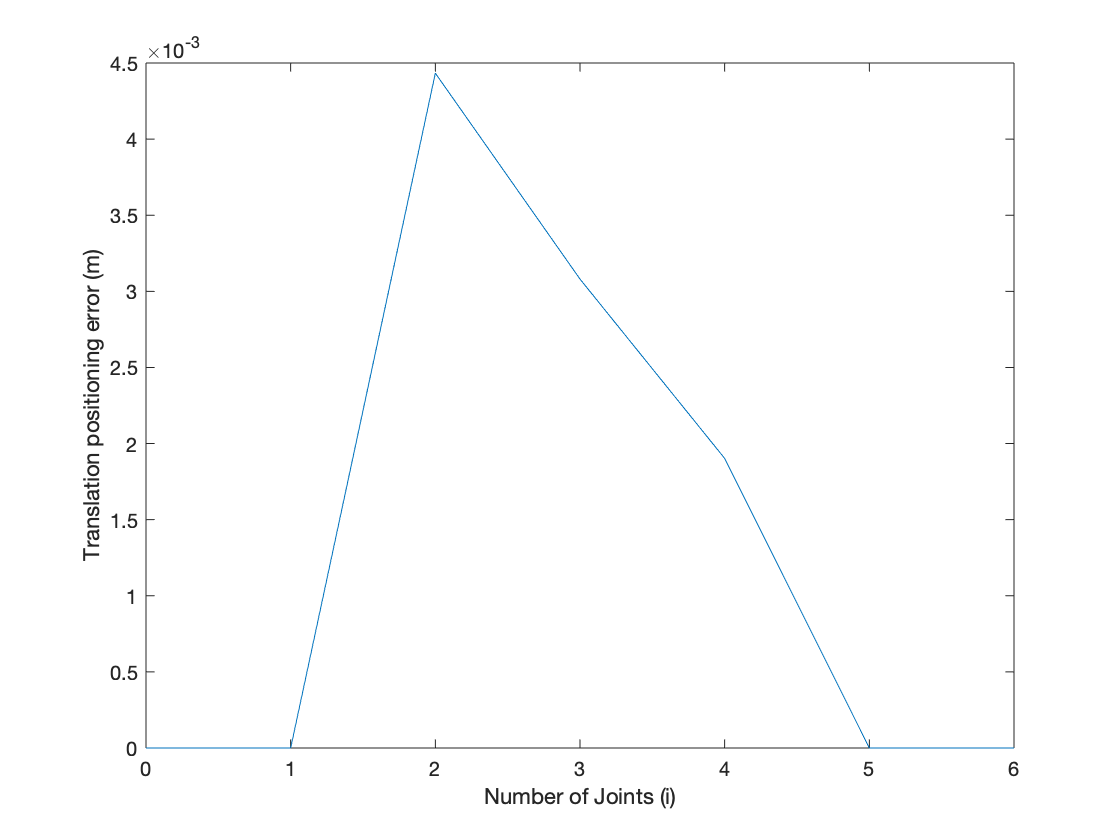

plot([0,1,2,3,4,5,6], [0,N1,N2,N3,N4,N5,N6]) % --> 6f)
xlabel("Number of Joints (i)")
ylabel("Translation positioning error (m)")